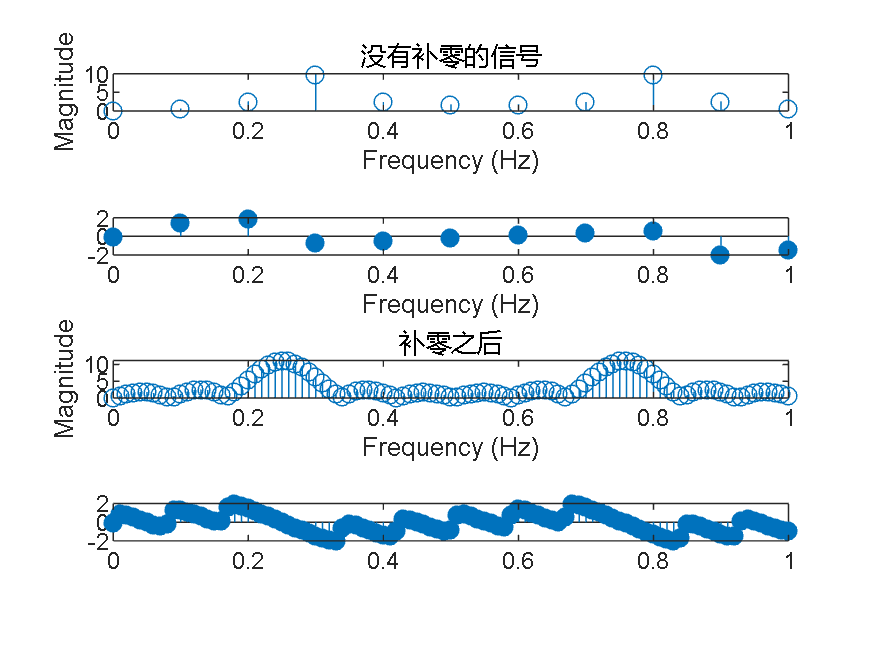

%2.1(1)
clear,close all,clc
% 信号参数
N = 10; % 信号长度
n = 0:N; % 时间向量

% 生成信号
x = cos(0.48*pi*n) + cos(0.52*pi*n);

% 计算DFT
X = fft(x);

% 计算频率向量
f = (0:N)/N;

% 绘制幅频响应

subplot(411)
    stem(f, abs(X));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title('没有补零的信号');
subplot(412)
    stem(f,angle(X),'filled');
    xlabel('Frequency (Hz)');

% 计算补零后的DFT
N1=100;
X_padded = fft(x,N1+1);

% 计算补零后的频率向量
f_padded=(0:N1)/N1;

% 绘制补零后的幅频响应
subplot(413)
    stem(f_padded, abs(X_padded));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title('补零之后');
subplot(414)
    stem(f_padded,angle(X_padded),"filled")

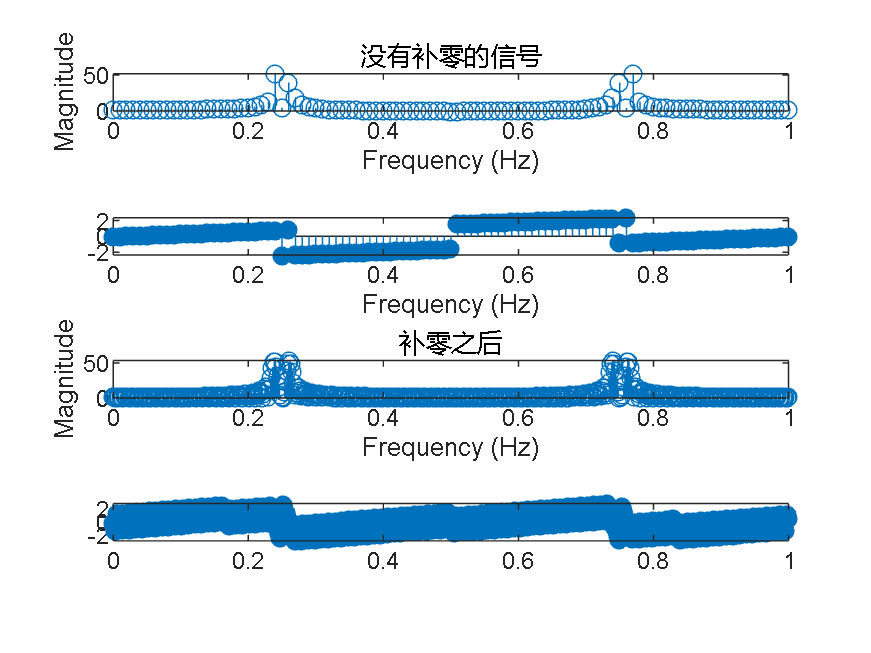

%2.1(2)
    clear,close all,clc
% 信号参数
N = 100; % 信号长度
n = 0:N; % 时间向量

% 生成信号
x = cos(0.48*pi*n) + cos(0.52*pi*n);

% 计算DFT
X = fft(x);

% 计算频率向量
f = (0:N)/N;

% 绘制幅频响应

subplot(411)
    stem(f, abs(X));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title('没有补零的信号');
subplot(412)
    stem(f,angle(X),'filled');
    xlabel('Frequency (Hz)');

% 计算补零后的DFT
N1=512;
X_padded = fft(x,N1+1);

% 计算补零后的频率向量
f_padded=(0:N1)/N1;

% 绘制补零后的幅频响应
subplot(413)
    stem(f_padded, abs(X_padded));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title('补零之后');
subplot(414)
    stem(f_padded,angle(X_padded),"filled")

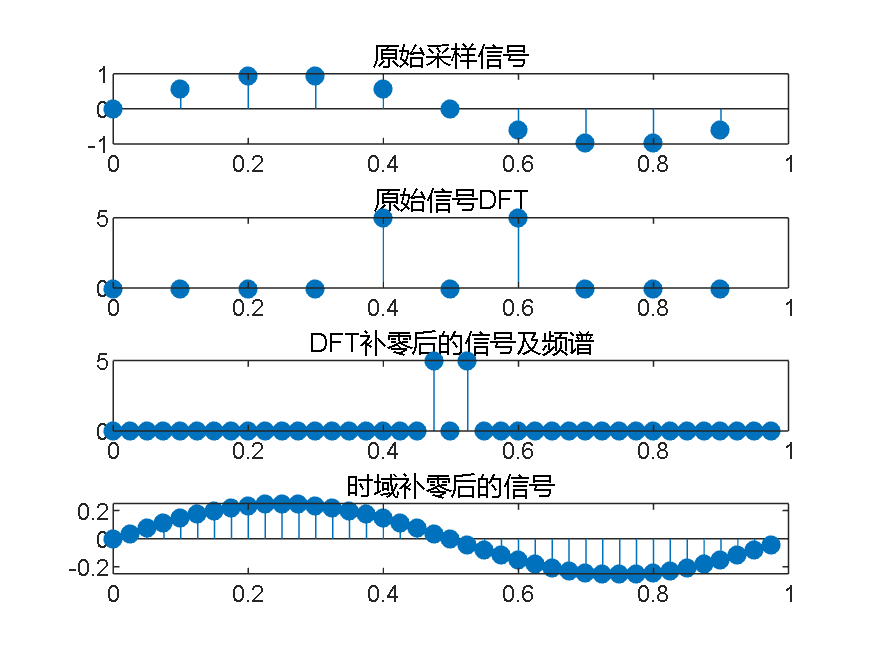

% 2.2(1)
clear
close all

% 原始信号
f = 1; % 信号频率为1Hz
Fs = 10; % 采样率为10Hz
T = 1; % 持续时间为1s
t = 0:1/Fs:T-1/Fs; 
original_signal = sin(2*pi*f*t); 

% subplot 1: 原始采样信号
subplot(4,1,1);
stem(t, original_signal, 'filled');
title('原始采样信号');

% subplot 2: 原始信号DFT
N = length(original_signal); % 原始信号长度
X = fft(original_signal, N);
X = fftshift(X); 
subplot(4,1,2)
stem(t, abs(X), 'filled')
title('原始信号DFT');

% subplot 3: DFT补零后的信号及频谱
target_sampling_rate = 40; % 目标采样率
L = target_sampling_rate/Fs; 
X1 = zeros(1, N*L); 
X1(N*L/2-N/2+1:N*L/2+N/2) = X; % 将原始频谱放入新的频谱序列
x1 = ifft(ifftshift(X1), N*L);
t1 = 0:1/target_sampling_rate:T-1/(target_sampling_rate*L); 
subplot(4,1,3)
stem(t1, fftshift(abs(fft(x1, N*L))), 'filled') % 计算插值后的频谱并绘制
title('DFT补零后的信号及频谱');

% subplot 4: 时域补零后的信号
subplot(4,1,4);
stem(t1, real(x1), 'filled');
title('时域补零后的信号');

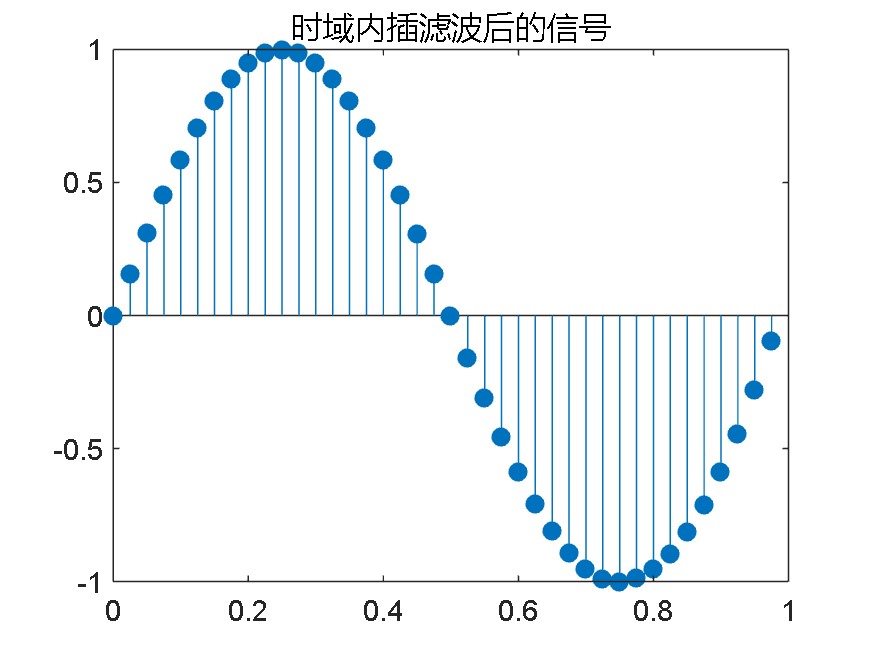


% 2.2(2)
% 时域内插滤波
new_t = 0:1/target_sampling_rate:T-1/target_sampling_rate; % 新的时间序列
new_signal = interp1(t, original_signal, new_t, 'spline'); % 内插滤波

figure
stem(new_t, new_signal, 'filled');
title('时域内插滤波后的信号');